# Model fitting for 71 localities in Colombia

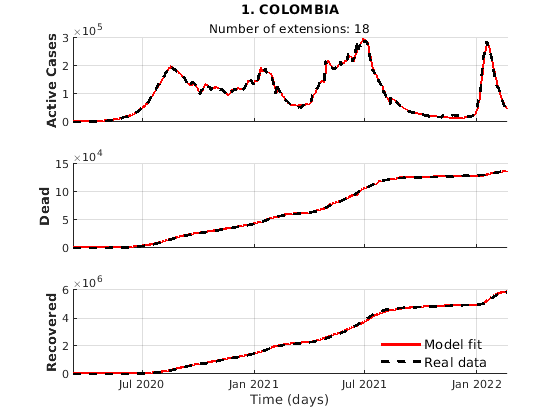

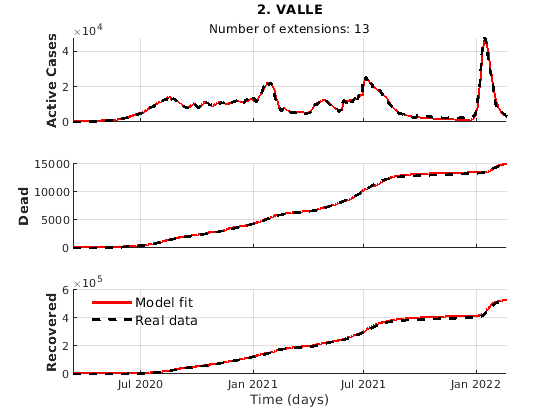

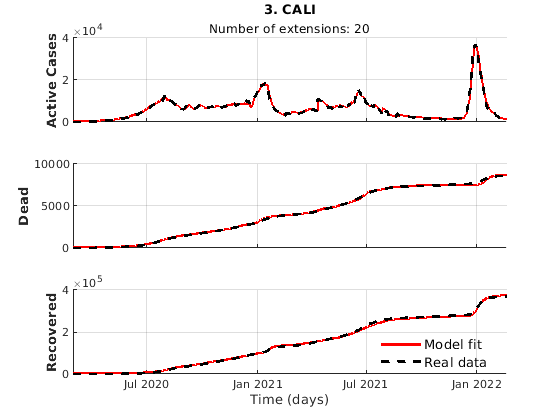

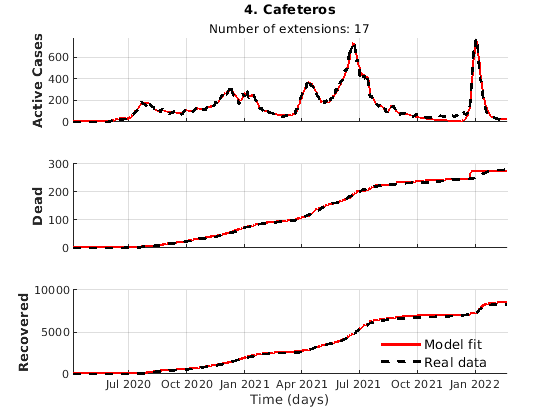

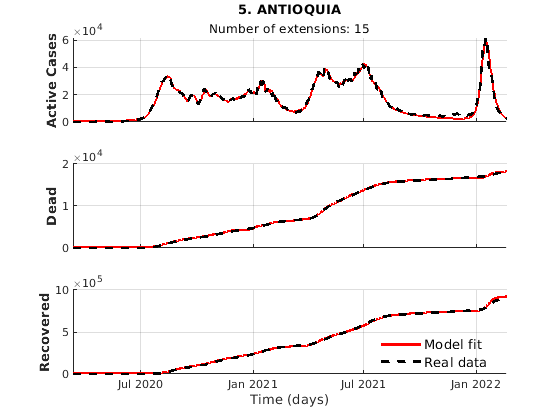

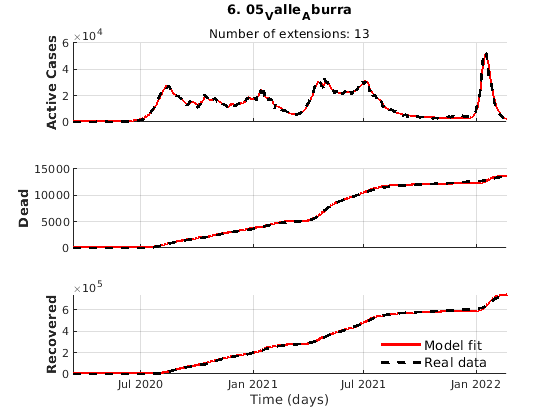

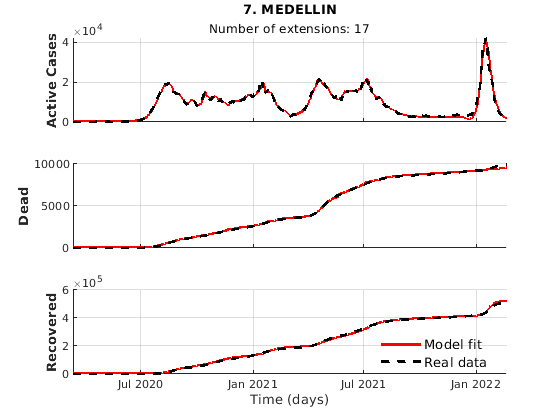

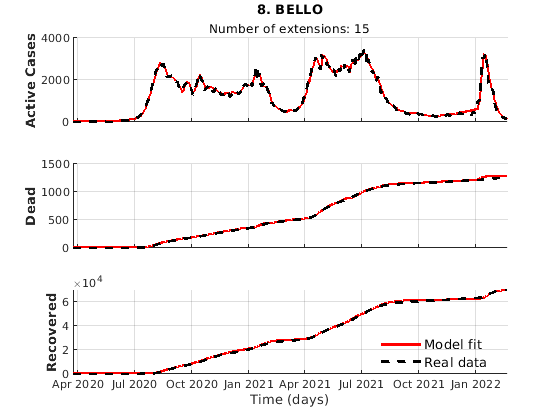

addpath Tool
addpath Model
addpath Data 
addpath ValidationFunctions

close all

opts = detectImportOptions('../localidades.csv');
opts = setvartype(opts, 1, 'string');
dataLocal = readtable('../localidades.csv', opts);
ListData = "co";          
Localities = [ListData; dataLocal{:,1}];

for i = 1: length(Localities)
    
    NameData = Localities(i);

    data = jsondecode(fileread("Outs/" + NameData + ".json"));
    load("Informs/" + NameData + "Inform.mat")
    ExtensionNumber = length(InformContainer);

    Names = InformContainer{1}.local;
    yfunction = [data.ActCasosSim, data.MuertesSim, data.RecuperadosSim];
  
    %%Create date in time-series
    
    t2 = datetime(2022,03,06);
    t1 = t2 - length(data.ActCasosSim)+1;
    t = t1:t2;
    
    figure

    subplot(3,1,1)    
    hold on 
    plot(t, data.ActCasosSim,'-r','LineWidth',2)   
    plot(t, data.ActCasos,'k--','LineWidth',2)
    set(gca,'xticklabel',{[]})
    ylabel('Active Cases','FontSize',10, 'FontWeight', 'bold')
    grid on
    xlim([t(1) t(end)-14]);

    title(string(i) + ". " + Names,'FontSize',10)
    subtitle("Number of extensions: " + ExtensionNumber)

    subplot(3,1,2)    
    hold on 
    plot(t,data.MuertesSim,'-r','LineWidth',2) 
    plot(t,data.Muertes,'k--','LineWidth',2)
    set(gca,'xticklabel',{[]})
    ylabel('Dead','FontSize',10, 'FontWeight', 'bold')
    grid on
    xlim([t(1) t(end)-14])

    subplot(3,1,3)
    hold on 
    plot(t,data.RecuperadosSim,'-r','LineWidth', 2);
    plot(t,data.Recuperados,'--k','LineWidth', 2);
    grid on
    ylabel('Recovered','FontSize',10, 'FontWeight', 'bold')
    xlabel('Time (days)','FontSize',10)
    legend('Model fit','Real data','box','off', 'Location','best','FontSize',10)
    xlim([t(1) t(end)-14]);
end